 setenv('ROS_MASTER_URI','http://192.168.11.128:11311')
 setenv('ROS_IP','192.168.11.128.1')
 rosinit

The value of the ROS_MASTER_URI environment variable, http://192.168.232.128:11311, will be used to connect to the ROS master.
The value of the ROS_IP environment variable, 192.168.232.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_74535 with NodeURI http://192.168.232.1:53886/ and MasterURI http://192.168.232.128:11311.



serviceclient = rossvcclient("/gazebo/reset_world");
call(serviceclient);
    velMsg.Linear.X = 0;  % Set linear velocity
    velMsg.Angular.Z = 0;  % Set angular velocity
    send(velPub, velMsg);

% Shutdown running connections
%rosshutdown;
% Init connection
%rosinit

[velPub,velMsg] = rospublisher("/cmd_vel");
odomSub = rossubscriber("/odom");
goalHandle = PoseHandle();
goalSub = rossubscriber("/move_base_simple/goal", @(src,msg)goalCallback(src,msg,goalHandle));

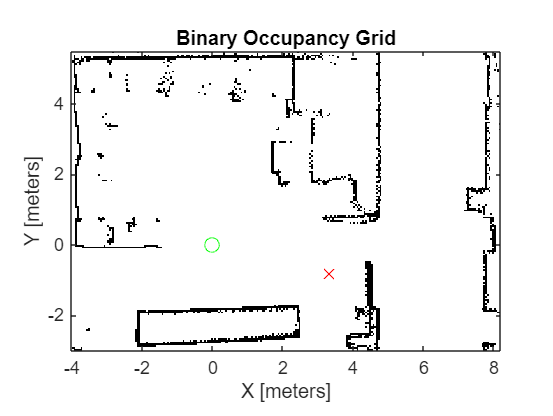

% Load image
map_img = imread("rst_lab_cropped.pgm");

% Required steps to align the map correctly (do not change!)
bwimage = map_img < 100;
bwimage = imrotate(bwimage, 90);
map = binaryOccupancyMap(bwimage,1/0.05);
map.GridLocationInWorld = [-4, -3];

% Visualization
figure(Name="Map");
map.show;
% get current robot pose
odomMsg = receive(odomSub);
[robot_pose(1),robot_pose(2),robot_pose(3)] = OdometryMsg2Pose(odomMsg);
hold on;
% plot robot pose
plot(robot_pose(1), robot_pose(2),'go',MarkerSize=8);
% plot goal pose
plot(goalHandle.x, goalHandle.y,'rx',MarkerSize=8);

Executing RRT


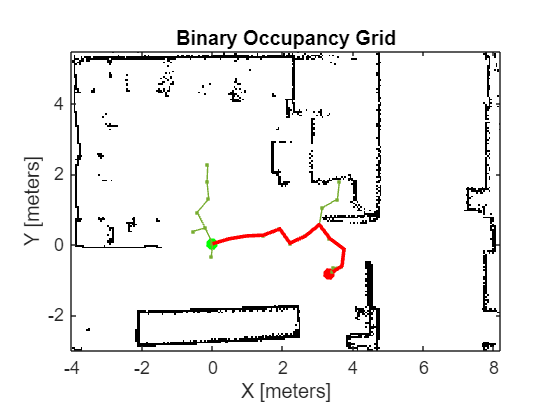

% generate global plan
global_planner ="RRT";

% get current pose
odomMsg = receive(odomSub);
[start_pose(1),start_pose(2),start_pose(3)] = OdometryMsg2Pose(odomMsg);

if global_planner=="PRM"
    disp("Executing PRM");
    stateSpace = stateSpaceSE2;
    stateSpace.StateBounds=[map.XWorldLimits;map.YWorldLimits;[-pi pi]];

    stateValidator=validatorOccupancyMap(stateSpace);
    stateValidator.Map=map;
    stateValidator.ValidationDistance=0.01;
    planner = plannerPRM(stateSpace,stateValidator,"MaxConnectionDistance",0.5,"MaxNumNodes",1000);

    graph = graphData(planner);
    edges = table2array(graph.Edges);
    nodes = table2array(graph.Nodes);

    show(stateValidator.Map);

    xlim(map.XWorldLimits);
    ylim(map.YWorldLimits);
    % visualize roadmap
    hold on
    % draw nodes
    plot(nodes(:,1),nodes(:,2),"*","Color","b","LineWidth",2)
    for i = 1:size(edges,1)
        % Samples states at distance 0.02 meters.
        states = interpolate(stateSpace,nodes(edges(i,1),:),nodes(edges(i,2),:),0:0.02:1);
        % draw edges
        plot(states(:,1),states(:,2),"Color","b")
    end

    goal_pose = goalHandle2goalPose(goalHandle);

    % Plot start and goal
    plot(start_pose(1), start_pose(2),"*","Color","g","LineWidth",3)
    plot(goal_pose(1), goal_pose(2),"*","Color","r","LineWidth",3)

    % plan path from start to goal
      [path, solnInfo] = plan(planner,start_pose,goal_pose)

    % visualize path
    if solnInfo.IsPathFound
        interpolate(path,1000);
        plot(path.States(:, 1), path.States(:, 2), "Color",[0.85 0.325 0.098],"LineWidth",2)
    else
        disp("Path not found")
    end
    hold off
    plannedPath = path.States;

elseif global_planner=="RRT"
    disp("Executing RRT");

    % Initialize state space and validator
    stateSpace = stateSpaceSE2;
    stateSpace.StateBounds=[map.XWorldLimits;map.YWorldLimits;[-pi pi]];

    stateValidator=validatorOccupancyMap(stateSpace);
    stateValidator.Map=map;
    stateValidator.ValidationDistance=0.01;

    % Init planner
    planner = plannerRRT(stateSpace,stateValidator,"MaxConnectionDistance",0.5,"MaxIterations",15000);


    goal_pose = goalHandle2goalPose(goalHandle);

    % Plan
    [path,solnInfo] = plan(planner,start_pose,goal_pose);

    % Display results
    show(stateValidator.Map);
    xlim(map.XWorldLimits);
    ylim(map.YWorldLimits);
    hold on
    % Plot start and goal
    plot(start_pose(1), start_pose(2),"*","Color","g","LineWidth",3)
    plot(goal_pose(1), goal_pose(2),"*","Color","r","LineWidth",3)
    
    % Plot Tree expansion
    plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-')
    % Draw path
    plot(path.States(:,1),path.States(:,2),'r-','LineWidth',2)
    drawnow;

    plannedPath=path.States;
else
    error("Unknown global planner.")
end

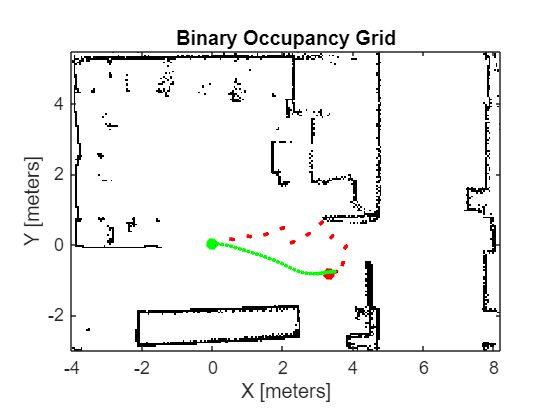

options = optimizePathOptions;
% options.ObstacleSafetyMargin=1;
options.MinTurningRadius= 0.01;
% options.MaxPathStates=200;
 inpath=path.States;

% Optimize the path generated by the planner.
[optimizedPath,kineticInfo,solutionInfo] = optimizePath(inpath,map,options);
figure;

% Display results
show(stateValidator.Map);
xlim(map.XWorldLimits);
ylim(map.YWorldLimits);
hold on
% Plot start pose and goal pose
plot(start_pose(1), start_pose(2),"*","Color","g","LineWidth",3)
plot(goal_pose(1), goal_pose(2),"*","Color","r","LineWidth",3)
% Draw path planned and optimized
%quiver(inpath(:,1),inpath(:,2),'r-','LineWidth',2)

quiver(inpath(:,1),inpath(:,2),cos(inpath(:,3)),sin(inpath(:,3)),0.1,'r-','LineWidth',2)
%plot(optimizedPath(:,1),optimizedPath(:,2),'g-','LineWidth',2)

quiver(optimizedPath(:,1),optimizedPath(:,2),cos(optimizedPath(:,3)),sin(optimizedPath(:,3)),0.1,'g-','LineWidth',2)
hold off;

% 

% TEB = true;
% 
% if TEB
% 
%     refpath = optimizedPath;
%     % Optimize the planned global path
%     optimizedPath = optimizePath(refpath, map);
% 
%     % Plot the optimized path alongside the original path
%     figure;
%     show(map);
%     hold on;
%     plot(refpath(:,1), refpath(:,2), 'b-', 'DisplayName', 'Original Path');
%     plot(optimizedPath(:,1), optimizedPath(:,2), 'r-', 'DisplayName', 'Optimized Path');
%     legend('Location', 'best');
%     title('Original vs Optimized Path');
% 
%     % Initiate TEB with parameters
%     teb = controllerTEB(optimizedPath, map);
%     teb.RobotInformation.Shape = "Rectangle";
%     teb.RobotInformation.Dimension = [0.2 0.2];
%     teb.LookAheadTime = 6.0;
%     teb.MaxVelocity = [1 1];
%     teb.MaxAcceleration = [0.5 0.5];
%     teb.ReferenceDeltaTime = 0.2;
%     teb.ObstacleSafetyMargin = 0.2;
% 
%     % Init values for variables
%     localmap = binaryOccupancyMap(15, 15, map.Resolution);
%     curvel = [0 0];
% 
%     goalReached = false;
%     maxSimTime = 300;
% 
%     %velMsg = rosmessage(velPub);
%     rateObj = rateControl(5);
% % Get pose
%         position = odomSub.LatestMessage.Pose.Pose.Position;
%         orientation = odomSub.LatestMessage.Pose.Pose.Orientation;
%         curpose(1) = position.X;
%         curpose(2) = position.Y;
%         eul = quat2eul([orientation.W, orientation.X, orientation.Y, orientation.Z]);
%         curpose(3) = eul(1); % yaw
% 
%         % Take last velocity
%         twist = odomSub.LatestMessage.Twist.Twist;
%         curvel = [twist.Linear.X, twist.Angular.Z];
% 
%     figure;
%     while ~goalReached && rateObj.TotalElapsedTime < maxSimTime
% 
%         % Update local map
%         moveMapBy = curpose(1:2) - localmap.XLocalLimits(end)/2;
%         localmap.move(moveMapBy, FillValue=0.5);
%         syncWith(localmap, map);
% 
%         % Generate new velocity commands with TEB
%         %tic;
%         [velcmds, tstamps, curpath, info] = step(teb, curpose, curvel);
%         %toc;
% 
%         % Check if goal is reached
%         goalReached = info.HasReachedGoal;
% 
%         % Check if replanning is needed
%         feasibleDriveDuration = tstamps(info.LastFeasibleIdx);
%         if info.LastFeasibleIdx ~= height(tstamps) && feasibleDriveDuration < (teb.LookAheadTime/3)
%             % Replan global path
%             route = planner.plan(curpose, goal_pose);
%             newPath = route.States;
%             %refpath = route.States;
% 
%             headingToNextPose = atan2(diff(newPath(:,2)), diff(newPath(:,1)));
%             %headingToNextPose = headingFromXY(refpath(:,1:2));
% 
%             newPath(2:end,3) = headingToNextPose;
%             %refpath(2:end-1,3) = headingToNextPose(2:end-1);
% 
%             optimizedPath = optimizePath(newPath, map);
% 
%             teb.ReferencePath = optimizedPath;
%             %teb.ReferencePath = refpath;
%         end
% 
%         % % Update robot pose using simple kinematic model
%         dt = tstamps(2) - tstamps(1);
%         curpose(1) = curpose(1) + velcmds(1,1) * cos(curpose(3)) * dt
%         curpose(2) = curpose(2) + velcmds(1,1) * sin(curpose(3)) * dt
%         curpose(3) = curpose(3) + velcmds(1,2) * dt
%         curvel = velcmds(1, :)
% 
% 
% 
% 
%         % Update robot pose using ODE solver
%         %dt = tstamps(2) - tstamps(1);
%         %[t, y] = ode45(@(t,y)stateSpace(t, y, velcmds(1,:)), [0 dt], curpose);
%         %curpose = y(end, :);
%         %curvel = velcmds(1, :);
%         %[t, y] = ode45(@(t,y) derivative(t, y, velcmds(1,:)), [0 dt], curpose);
% 
%         % Visualize
%         clf;
%         show(localmap);
%         hold on;
%         plot(optimizedPath(:,1), optimizedPath(:,2), ".-", Color="#EDB120", DisplayName="Optimized Path");
%         quiver(curpath(:,1), curpath(:,2), cos(curpath(:,3)), sin(curpath(:,3)), 0.2, Color="#A2142F", DisplayName="Current Path");
%         quiver(curpose(1), curpose(2), cos(curpose(3)), sin(curpose(3)), 0.5, "o", MarkerSize=10, ShowArrowHead="off", Color="#D95319", DisplayName="Current Robot Pose");
%         legend('Location', 'best');
%         title('Robot Progress');
%         drawnow;
% 
%         % Publish velocity commands
%         velMsg.Linear.X = curvel(1);
%         velMsg.Angular.Z = curvel(2);
%         send(velPub, velMsg);
% 
%         waitfor(rateObj);
%     end
%     velMsg.Linear.X = 0;  % Set linear velocity
%     velMsg.Angular.Z = 0;  % Set angular velocity
%     send(velPub, velMsg);
% 
% else
%     error("Unknown local planner");
% end

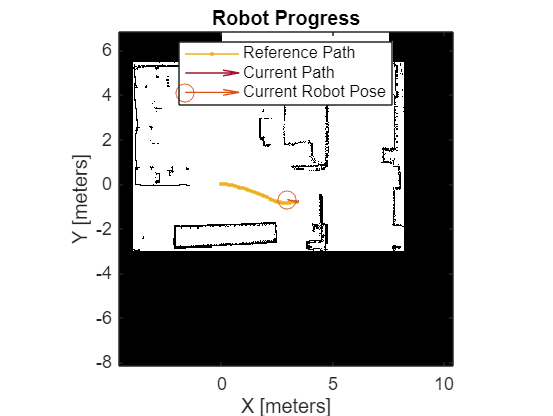

TEB = true;
if TEB
    % Optimize the planned global path
 
    refpath = optimizedPath;

    % Initiate TEB with parameters
    teb = controllerTEB(optimizedPath, map);
    teb.RobotInformation.Shape = "Rectangle";
    teb.RobotInformation.Dimension = [0.2 0.2];
    teb.LookAheadTime = 8.0;
    teb.MaxVelocity = [0.5 1];
    teb.MaxAcceleration = [0.5 0.5];
    teb.ReferenceDeltaTime = 0.3;
    teb.ObstacleSafetyMargin = 0.5;
    %teb.GoalTolerance = [0.1 0.1 0.1]
    % Init values for variables
    localmap = binaryOccupancyMap(15, 15, map.Resolution);
    curvel = [0 0];
    goalReached = false;
    rateObj=rateControl(5);
    while ~goalReached
        % Get pose
        position = odomSub.LatestMessage.Pose.Pose.Position;
        orientation = odomSub.LatestMessage.Pose.Pose.Orientation;
        curpose(1) = position.X;
        curpose(2) = position.Y;
        eul = quat2eul([orientation.W, orientation.X, orientation.Y, orientation.Z]);
        curpose(3) = eul(1); % yaw

        % Take last velocity
        twist = odomSub.LatestMessage.Twist.Twist;
        curvel = [twist.Linear.X, twist.Angular.Z];

        % Update local map
        moveMapBy = curpose(1:2) - localmap.XLocalLimits(end)/2;
        localmap.move(moveMapBy, FillValue=0.5);
        syncWith(localmap, map);

        % Generate new vel commands with teb
      
        [velcmds,tstamps,curpath,info] =step(teb,curpose,curvel);
        

        if isempty(velcmds)
            disp('TEB failed to find a solution. Replanning...');
            % Replan logic here
             route = planner.plan(curpose, goal_pose);
            if isempty(route)
                 disp('Failed to replan path.');
    
                continue;
            end
             refpath = route.States;
        headingToNextPose = headingFromXY(refpath(:,1:2));
        refpath(2:end-1,3) = headingToNextPose(2:end-1);
        teb.ReferencePath = refpath;
        end

        % Check if goal is reached
        goalReached = norm(curpose(1:2) - goal_pose(1:2)) < 0.3 && abs(angdiff(curpose(3), goal_pose(3))) < 1;
        % end_pos=norm(curpose(1:2) - goal_pose(1:2))
        % end_ori=abs(angdiff(curpose(3), goal_pose(3)))
        feasibleDriveDuration = tstamps(info.LastFeasibleIdx);
        if info.LastFeasibleIdx ~= height(tstamps) && ...
           feasibleDriveDuration < (teb.LookAheadTime/3)
            route = planner.plan(curpose, goal_pose);
            refpath = route.States;
            headingToNextPose = headingFromXY(refpath(:,1:2));
            refpath(2:end-1,3) = headingToNextPose(2:end-1);
            teb.ReferencePath = refpath;
        end
            
        % Optional: Check if the goal is reached in between the commands
            if goalReached
                break;
            end
        % Show the updated information input to or output from controllerTEB
        clf;
        show(localmap);
        hold on;
        plot(refpath(:,1), refpath(:,2), ".-", 'Color', "#EDB120", 'DisplayName', "Reference Path")
        quiver(curpath(:,1), curpath(:,2), cos(curpath(:,3)), sin(curpath(:,3)), 0.2, 'Color', "#A2142F", 'DisplayName', "Current Path")
        quiver(curpose(1), curpose(2), cos(curpose(3)), sin(curpose(3)), 0.5, "o", 'MarkerSize', 10, 'ShowArrowHead', "off", 'Color', "#D95319", 'DisplayName', "Current Robot Pose");
        legend('Location', 'best');
        title('Robot Progress');
        drawnow;

        % % Send velocities to robot
        % cmd_vel.Linear.X = velcmds(1,1);
        % cmd_vel.Angular.Z = velcmds(1,2);
        % send(velPub, cmd_vel);
  % Publish velocity commands
      
            velMsg.Linear.X = velcmds(1, 1);  % Set linear velocity
            velMsg.Angular.Z = velcmds(1, 2); % Set angular velocity
            send(velPub, velMsg);             % Publish the message
            waitfor(rateObj);                 % Maintain the loop rate

    end
    velMsg.Linear.X = 0;  % Set linear velocity
    velMsg.Angular.Z = 0;  % Set angular velocity
    send(velPub, velMsg);
else
    error("Unknown local planner");
end

### Helper functions you have to implement

function [] = goalCallback(~, msg, goalHandle)
    
    goalHandle.x = msg.Pose.Position.X;
    goalHandle.y = msg.Pose.Position.Y;
    eul = quat2eul([msg.Pose.Orientation.W, msg.Pose.Orientation.X, ...
                    msg.Pose.Orientation.Y, msg.Pose.Orientation.Z]);
    goalHandle.theta = eul(1); % Extract yaw angle
    disp("Received goal");
end

### Helper functions that are given

function [ x, y, theta ] = OdometryMsg2Pose(poseMsg)
% convert odometry message to vector
% 2007 - Frank Hoffmann
x=poseMsg.Pose.Pose.Position.X;
y=poseMsg.Pose.Pose.Position.Y;
eul=quat2eul([poseMsg.Pose.Pose.Orientation.W poseMsg.Pose.Pose.Orientation.X  poseMsg.Pose.Pose.Orientation.Y poseMsg.Pose.Pose.Orientation.Z]);
theta=eul(1);
end

function goalPose = goalHandle2goalPose(goalHandle)
goalPose = [goalHandle.x,goalHandle.y,goalHandle.theta];
end
